clear
%音声ファイルのリストの取得


%[audioIn,fs] = audioread('test_dataset/***.wav');



%dataSetDir = "C:\Users\Anzai Riki\Desktop\Creative_factory_bit_2022";
%signalDir = fullfile(dataSetDir,'test_dataset');
%sgds = signalDatastore(audioIn);


listing = dir('train/train_4/normal/*.wav')

listing = フィールドをもつ 834×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


listing(1).name

ans = 'normal_49931_PV_L15000_0.wav'

length(listing)

ans = 834


%{
for n = 1:length(listing)
    % ファイルのフルパスを取得
    fullpath = fullfile(listing(n).folder, listing(n).name);
end
%}
%fullpath = fullfile('C:\Users\Anzai Riki\Desktop\Creative_factory_bit_2022\test_dataset\*.wav');

%メルスペクトログラム

for i = 381:length(listing)
    fullpath = fullfile(listing(i).folder, listing(i).name);
    [audioIn,fs] = audioread(fullpath);
    %S = melSpectrogram(audioIn,fs);
    %plot(audioIn);
    %[numBands,numFrames] = size(S);
    %fprintf("Number of bandpass filters in filterbank: %d\n",numBands);
    %fprintf("Number of frames in spectrogram: %d\n",numFrames);
    
    figure('visible', 'off')
    hold on
    melSpectrogram(audioIn,fs);
    
    ax = gca;
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    colorbar('off');
    
    %figureの画像を保存
    name = ['chart',num2str(i),'.png'];
    saveas(gcf,name)
    hold off
end

%hold off

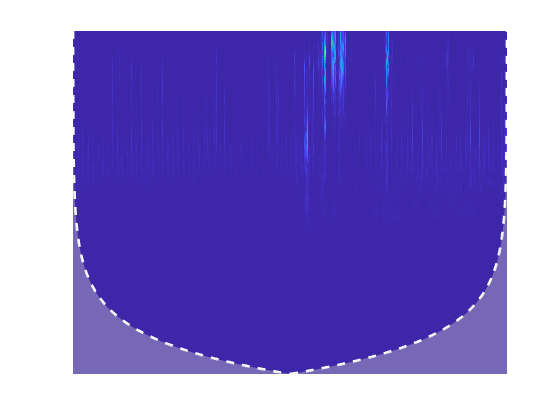

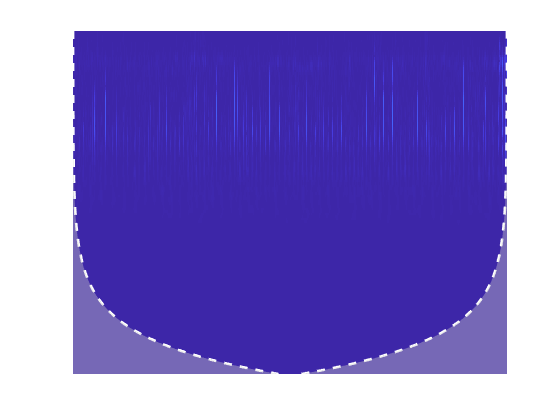

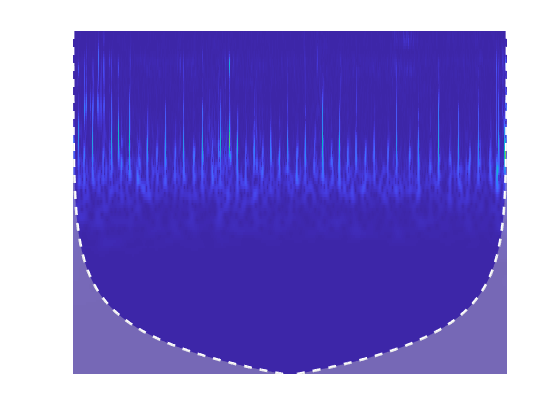

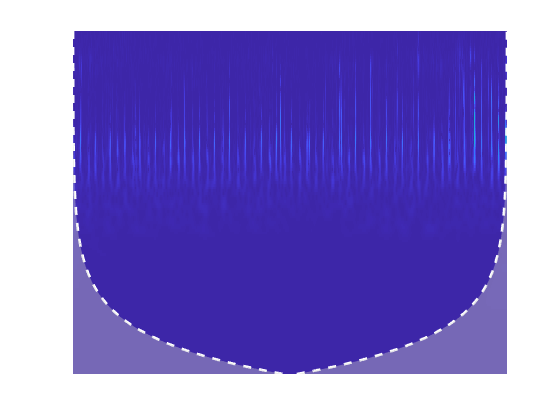

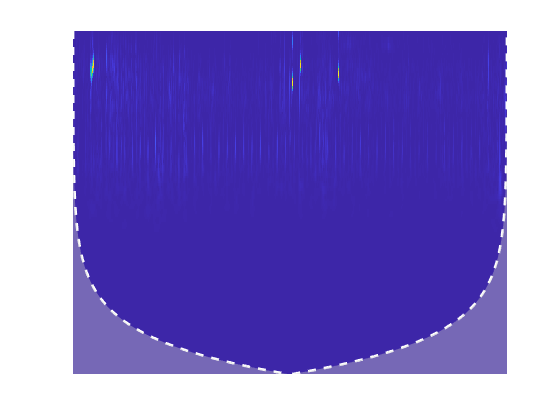

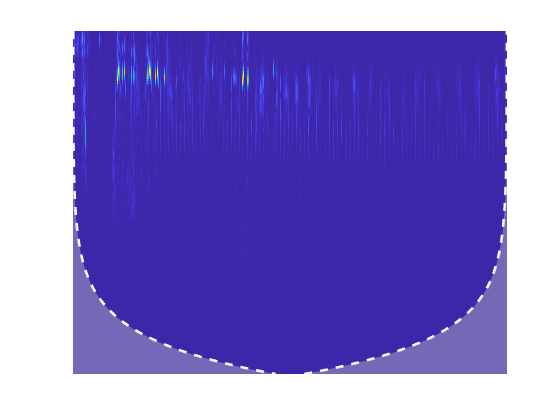

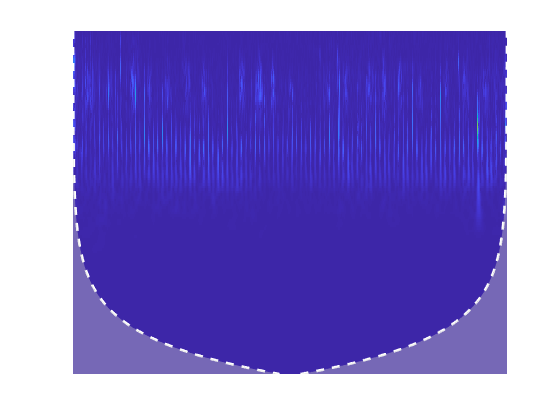

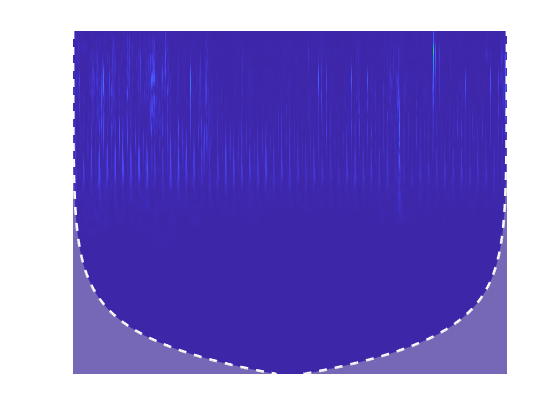

%ウェーブレット変換(今回は不使用)
%{
for i = 1:length(listing)
    fullpath = fullfile(listing(i).folder, listing(i).name);
    [audioIn,fs] = audioread(fullpath);
    
    [wt,f] = cwt(audioIn);
    
    figure
    hold on
    cwt(audioIn,1);
    
    ax = gca;
    ax.YAxis.Visible = 'off';
    ax.XAxis.Visible = 'off';
    colorbar('off');
    title([]);
    
    %figureの画像を保存
    name = ['chart',num2str(i),'.png']
    saveas(gcf,name)
end

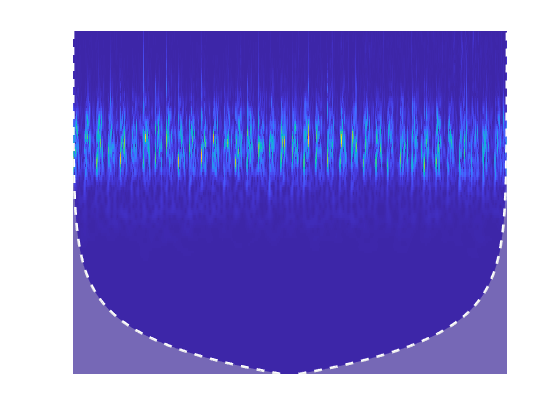


hold off


%}

%clear

%画像の読み込み
dataSetDir = "C:\Users\Anzai Riki\Desktop\Creative_factory_bit_2022/image/";
imageDir_train = fullfile(dataSetDir,{'train0';'train1';'train2';'train3'});
imageDir_val = fullfile(dataSetDir,'train4');
imageDir_test = fullfile(dataSetDir,'test');


imds = imageDatastore(imageDir_train,'IncludeSubfolders',true,"LabelSource","foldernames");
imdsval = imageDatastore(imageDir_val,'IncludeSubfolders',true,"LabelSource","foldernames");
imdstest = imageDatastore(imageDir_test,'IncludeSubfolders',true,"LabelSource","foldernames");







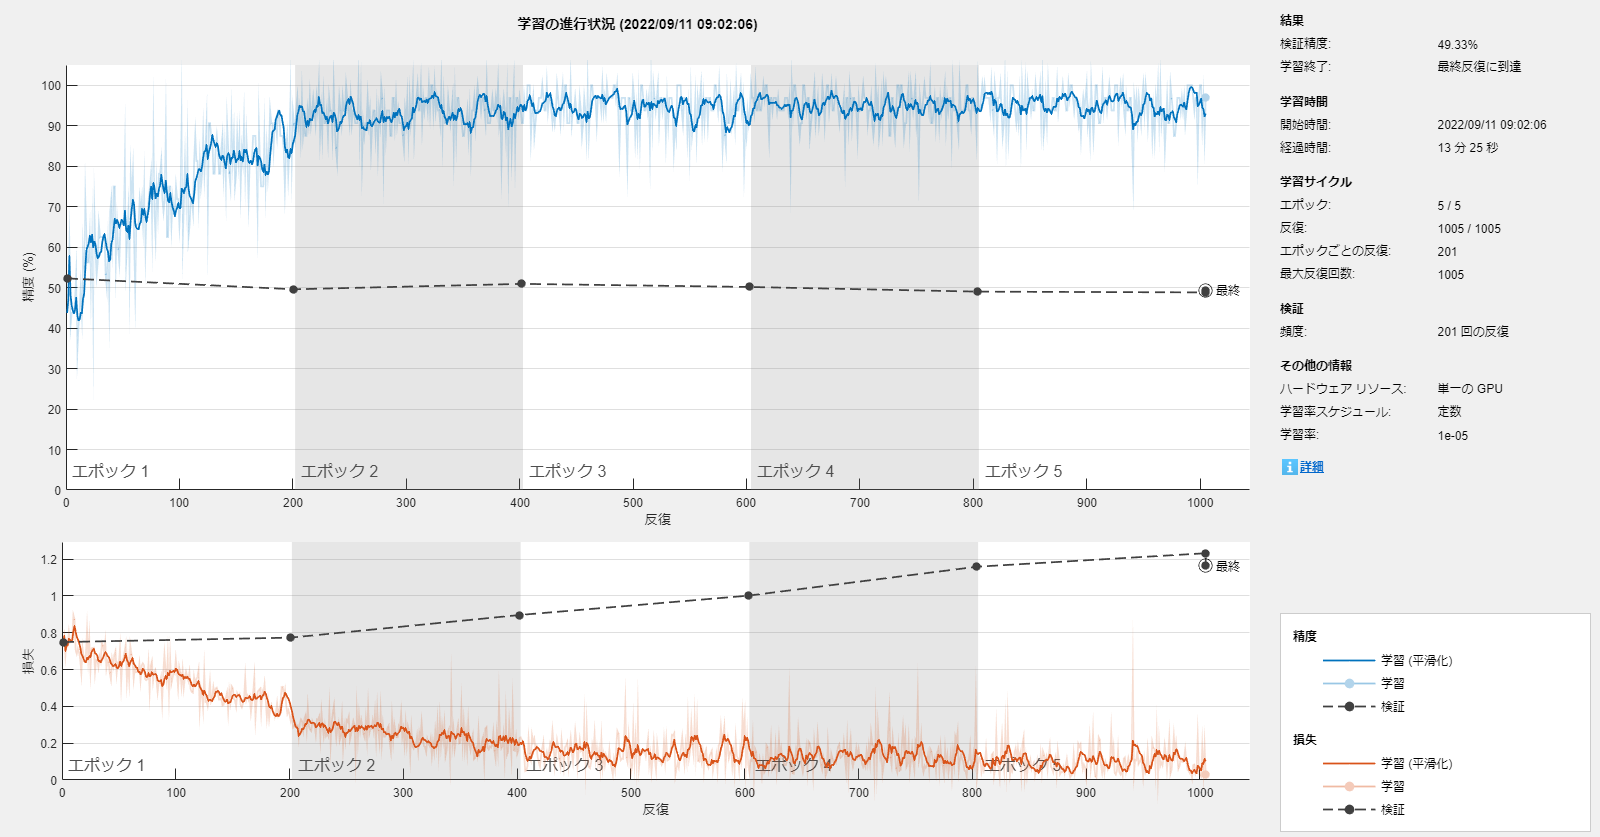

%resnet
net = resnet50();
%analyzeNetwork(net)

lgraph = layerGraph(net);
%inputSize = [656 875 3];
%plot(lgraph)
numClasses = 2;

%全結合層を置き換えたい
%全結合層の新しいやつ
newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

%全結合層付け替え
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);

%出力層の新しいやつ
newClassLayer = classificationLayer('Name','new_classoutput');

%出力層付け替え
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

%analyzeNetwork(lgraph)



augimdsTrain = augmentedImageDatastore([224 224 3],imds);
augimdsVal = augmentedImageDatastore([224 224 3],imdsval);
augimdsTest = augmentedImageDatastore([224 224 3],imdstest);

batch = 32;

valFrequency = floor(numel(augimdsTrain.Files)/batch);

%{
options = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',5, ...
    'MiniBatchSize',2, ...
    'VerboseFrequency',10);
%}

options = trainingOptions('adam', ...
    'MiniBatchSize',batch, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-5, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsVal, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

n = trainNetwork(augimdsTrain,lgraph,options);

%分類
%{
[YPred,probs] = classify(n,augimdsVal);
accuracy_val = mean(YPred == imdsval.Labels)
%}

[YPred2,probs2] = classify(n,augimdsTest);
accuracy_test = mean(YPred2 == imdstest.Labels)

accuracy_test = 0.5417

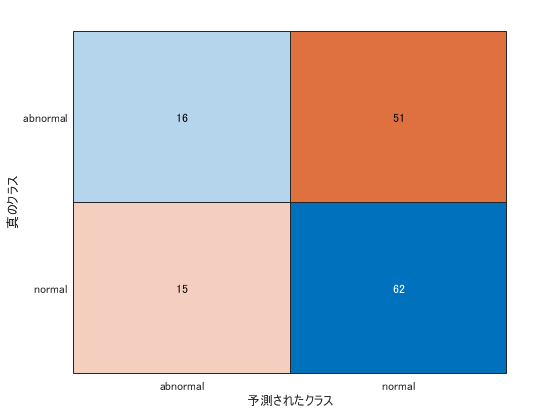

%混同行列
classNames = imdstest.Labels;
figure
confusionchart(classNames,YPred2)


% ROC曲線の表示
[X,Y,T,AUC] = perfcurve(imdstest.Labels,probs2(:,1),'abnormal');
AUC

AUC = 0.6094

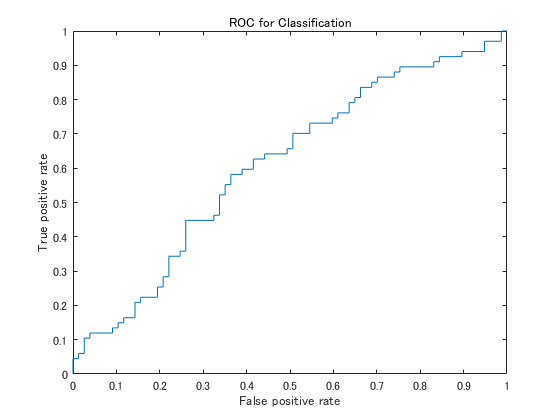

plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification')